# Próbkowanie sygnałów analogowych

A)

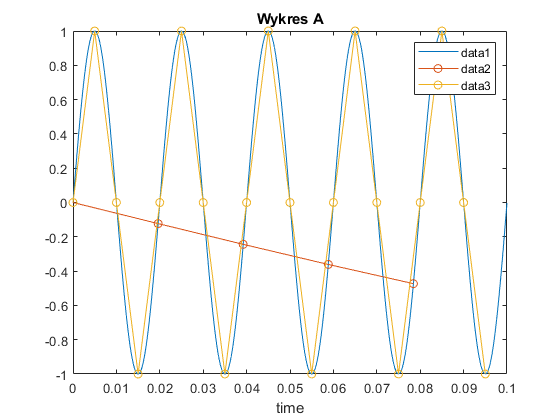

init1.fs = 50;
init1.end_time = 0.1;
init1.a = 230;

gen1.f10kHz =  arrayfun(@(p) sin(2*p*pi*init1.fs), [0:0.00001:init1.end_time-0.00001]);
gen1.f51Hz = arrayfun(@(p) sin(2*p*pi*init1.fs), [0:1/51:init1.end_time-1/51]);
gen1.f200Hz = arrayfun(@(p) sin(2*p*pi*init1.fs), [0:0.005:init1.end_time-0.005]);

clf
figure(1)
plot([0:0.00001:init1.end_time-0.00001],gen1.f10kHz)
hold on
plot([0:1/51:init1.end_time-1/51],gen1.f51Hz,'-o')
plot([0:0.005:init1.end_time-0.005],gen1.f200Hz,'-o')
set(gca,'XLim', [0,0.1])

legend('show')
xlabel('time')

title('Wykres A')

B)